clear;clf;
[t,data,f,sample_rate]= ComtradeRead();
t = t/1000;

% 整定值
z_this = 8.5088 + 1j*274.86;
z_next = 7.6767 + 1j*212.15;
z_this_0 = 243.25 + 1j*889.83;
k = (z_this_0-z_this)/z_this;

z_zone_1 = 0.8*z_this;
c_zone_1 = 2;
in_zone1 = @(x) abs(x-0.5*z_zone_1) <= 0.5*abs(z_zone_1);

z_zone_2 = 1.25*z_this;
c_zone_2 = 15;
in_zone2 = @(x) abs(x-0.5*z_zone_2) <= 0.5*abs(z_zone_2);

z_zone_3 = 1*z_this + 1.25*z_next;
c_zone_3 = 35;
in_zone3 = @(x) abs(x-0.5*z_zone_3)<= 0.5*abs(z_zone_3);

% 计算相量
Ia = phas(t,data(:,1),f,sample_rate);
Ib = phas(t,data(:,2),f,sample_rate);
Ic = phas(t,data(:,3),f,sample_rate);
Va = phas(t,data(:,4),f,sample_rate);
Vb = phas(t,data(:,5),f,sample_rate);
Vc = phas(t,data(:,6),f,sample_rate);
I0 = (Ia+Ib+Ic)/3;


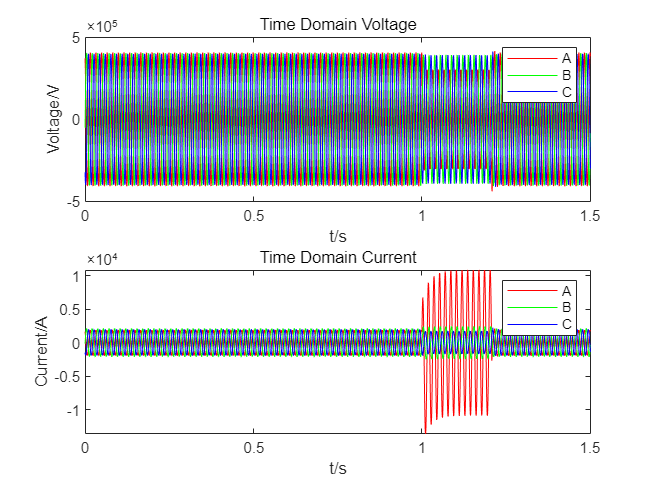

% 时域波形
subplot(211)
plot(t,data(:,4),'r',t,data(:,5),'g',t,data(:,6),'b')
xlabel("t/s")
ylabel("Voltage/V")
title("Time Domain Voltage")
legend("A","B","C")

subplot(212)
plot(t,data(:,1),'r',t,data(:,2),'g',t,data(:,3),'b')
xlabel("t/s")
ylabel("Current/A")
title("Time Domain Current")
legend("A","B","C")

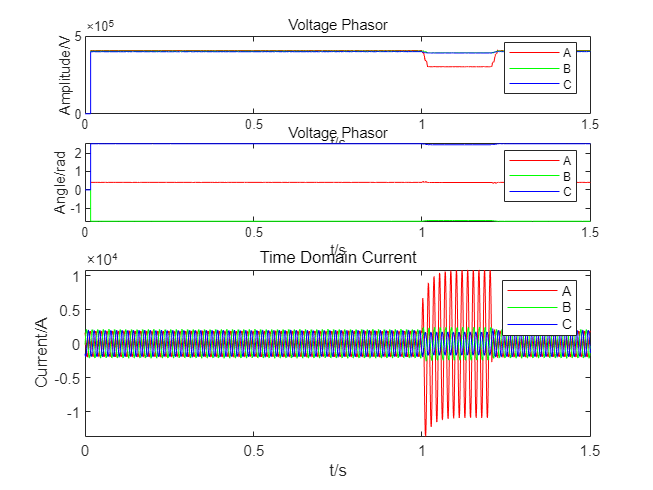

% 相量
temp = zeros(80,1);

subplot(411)
plot(t,abs([temp;Va]),'r',t,abs([temp;Vb]),'g',t,abs([temp;Vc]),'b')
xlabel("t/s")
ylabel("Amplitude/V")
title("Voltage Phasor")
legend("A","B","C")

subplot(412)
plot(t,angle([temp;Va]),'r',t,angle([temp;Vb]),'g',t,angle([temp;Vc]),'b')
xlabel("t/s")
ylabel("Angle/rad")
title("Voltage Phasor")
legend("A","B","C")

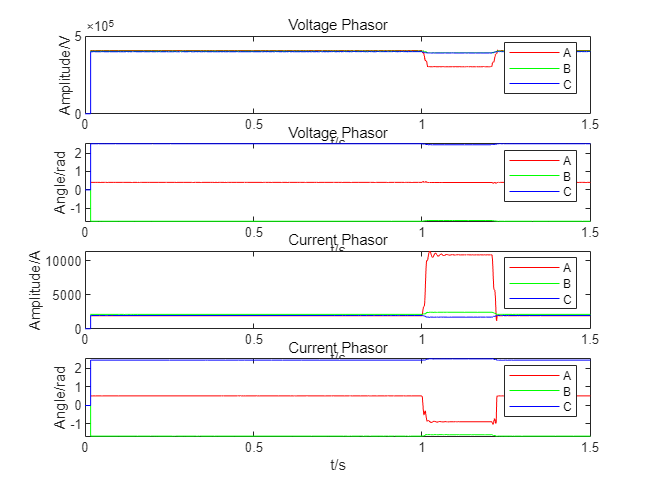


subplot(413)
plot(t,abs([temp;Ia]),'r',t,abs([temp;Ib]),'g',t,abs([temp;Ic]),'b')
xlabel("t/s")
ylabel("Amplitude/A")
title("Current Phasor")
legend("A","B","C")

subplot(414)
plot(t,angle([temp;Ia]),'r',t,angle([temp;Ib]),'g',t,angle([temp;Ic]),'b')
xlabel("t/s")
ylabel("Angle/rad")
title("Current Phasor")
legend("A","B","C")

% Trip
z = [Va./Ia,Vb./Ib,Vc./Ic,(Va-Vb)./(Ia-Ib),(Vb-Vc)./(Ib-Ic),(Vc-Va)./(Ic-Ia),Va./(Ia+k*I0),Vb./(Ib+k*I0),Vc./(Ic+k*I0)];
counters = zeros(3,9);

z_zone = [z_zone_1,z_zone_2,z_zone_3];
c_zone = [c_zone_1,c_zone_2,c_zone_3]./f;

sample_rate = 4800;
dt = 1/sample_rate;

tripped = 0;

for i=1:length(t)-80
    for j=1:9
        if in_zone1(z(i,j))
            counters(1,j) = counters(1,j) + dt;
            if counters(1,j) >= c_zone_1/f
                fprintf("Relay %d trips at t = %f s of Zone 1",j,t(i+80));
                tripped = 1;                
            end
        else
            counters(1,j) = 0;
        end
        if in_zone2(z(i,j))
            counters(2,j) = counters(2,j) + dt;
            if counters(2,j) >= c_zone_2/f
                fprintf("Relay %d trips at t = %f s of Zone 2",j,t(i+80));
                tripped = 1;                
            end
        else
            counters(2,j) = 0;
        end
        if in_zone3(z(i,j))
            counters(3,j) = counters(3,j) + dt;
            if counters(3,j) >= c_zone_3/f
                fprintf("Relay %d trips at t = %f s of Zone 3",j,t(i+80));
                tripped = 1;                
            end
        else
            counters(3,j) = 0;
        end
    end
    if tripped == 1
        break
    end
end

Relay 7 trips at t = 1.035618 s of Zone 1

if tripped == 0
        fprintf("There is no fault in all the operating regions!");
end

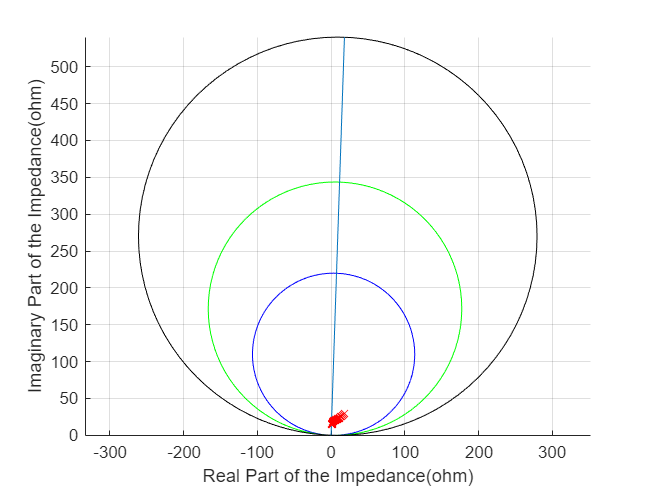

% 单个图
clf;
grid on
hold on
rectangle('Position',[0.5*real(z_zone_1)-0.5*abs(z_zone_1),0.5*imag(z_zone_1)-0.5*abs(z_zone_1),abs(z_zone_1),abs(z_zone_1)],'Curvature',[1,1],'EdgeColor','b')
rectangle('Position',[0.5*real(z_zone_2)-0.5*abs(z_zone_2),0.5*imag(z_zone_2)-0.5*abs(z_zone_2),abs(z_zone_2),abs(z_zone_2)],'Curvature',[1,1],'EdgeColor','g')
rectangle('Position',[0.5*real(z_zone_3)-0.5*abs(z_zone_3),0.5*imag(z_zone_3)-0.5*abs(z_zone_3),abs(z_zone_3),abs(z_zone_3)],'Curvature',[1,1])
line([0,real(z_zone_3)],[0,imag(z_zone_3)])
axis equal

plot(real(z(4769:4881,7)),imag(z(4769:4881,7)),"Marker","x","Color",'r','LineStyle','none');
xlabel("Real Part of the Impedance(ohm)")
ylabel("Imaginary Part of the Impedance(ohm)")

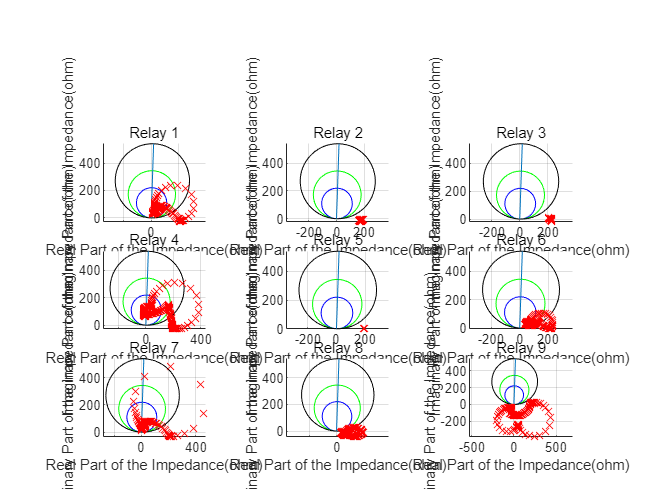

% 多个图
clf;

for i=1:9
    subplot(3,3,i)
    grid on
    hold on
    rectangle('Position',[0.5*real(z_zone_1)-0.5*abs(z_zone_1),0.5*imag(z_zone_1)-0.5*abs(z_zone_1),abs(z_zone_1),abs(z_zone_1)],'Curvature',[1,1],'EdgeColor','b')
    rectangle('Position',[0.5*real(z_zone_2)-0.5*abs(z_zone_2),0.5*imag(z_zone_2)-0.5*abs(z_zone_2),abs(z_zone_2),abs(z_zone_2)],'Curvature',[1,1],'EdgeColor','g')
    rectangle('Position',[0.5*real(z_zone_3)-0.5*abs(z_zone_3),0.5*imag(z_zone_3)-0.5*abs(z_zone_3),abs(z_zone_3),abs(z_zone_3)],'Curvature',[1,1])
    line([0,real(z_zone_3)],[0,imag(z_zone_3)])
    axis equal
    plot(real(z(:,i)),imag(z(:,i)),"Marker","x","Color",'r','LineStyle','none');
    xlabel("Real Part of the Impedance(ohm)")
    ylabel("Imaginary Part of the Impedance(ohm)")
    title_str = ['Relay ',num2str(i)];
    title(title_str)

end